# **Численные методы в СПб АУ РАН**

## **Задание по практике №5**

Кузьмичев Артём, 4 курс

## **№13 **

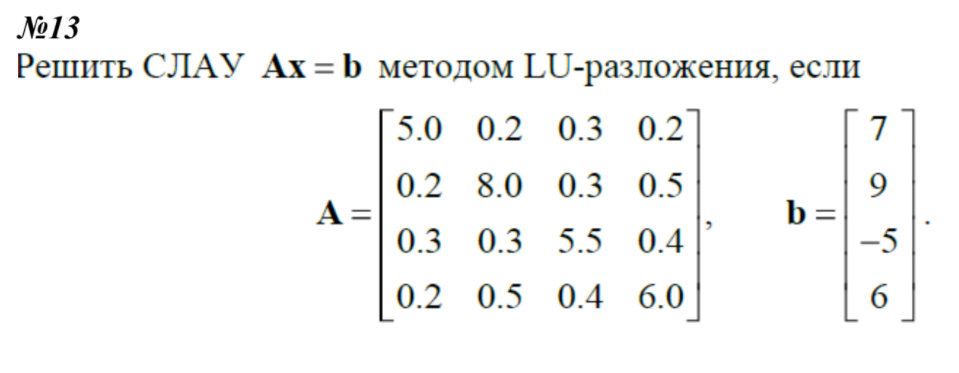

## Решение:

Инициализируем матрицу A и столбец b из условия

A = ...
[
    5.0,    0.2,    0.3,    0.2 ;
    0.2,    8.0,    0.3,    0.5 ;
    0.3,    0.3,    5.5,    0.4 ;
    0.2,    0.5,    0.4,    6.0 ;
];

b = ...
[
   7;
   9;
  -5;
   6;
];


Разложим систему c помощью функции lufact (опредление в конце скрипта .mlx) 

Хранение информации о LU-декомпозиции в едином массиве позволяет сохранить её более компактно. В $\textrm{LU}$ выше диагонали указаны элементы $U$, а ниже диагонали - недиагональные элементы $L$

[LU, R] = lufact(A)

LU =     5.0000    0.2000    0.3000    0.2000
    0.0400    7.9920    0.2880    0.4920
    0.0600    0.0360    5.4716    0.3703
    0.0400    0.0616    0.0677    5.9367


R =      1     2     3     4


Убедимся, что результат эквивалентен выводу встроенной функции

[L, U, R1] = lu(A)

L =     1.0000         0         0         0
    0.0400    1.0000         0         0
    0.0600    0.0360    1.0000         0
    0.0400    0.0616    0.0677    1.0000


U =     5.0000    0.2000    0.3000    0.2000
         0    7.9920    0.2880    0.4920
         0         0    5.4716    0.3703
         0         0         0    5.9367


R1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Чтобы это проверить, найдём разность $L$ и единичной матрицы (тем самым получив исключительно элементы $\textrm{LU}$ под диагонально) и сложим с $U$. Должна получиться матрица $\textrm{LU}$


$$\textrm{LU}=\left(L-{\textrm{id}}_N \right)+U$$


Посмотрим, совпадают ли элементы на каждой позиции

[~,N]=size(A);
round(LU-(L-eye(N))-U)== zeros(N) 

ans = 4×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


Обратную перестановку к $R_1$ можно получить транспонированием: ${R_1 }^{-1} ={R_1 }^T$ Если теперь переставить ${R_1 }^{-1}$ строки с помощью $R$, должна получиться тождественная перестановка, т.е. единичная матрица

Rinv = R1';
Rinv(R,:) == eye(N)

ans = 4×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


Решим систему c помощью функции lusolve (опредление в конце скрипта .mlx) 

X = lusolve(LU,R,b)

X =     1.3862
    1.0734
   -1.1115
    0.9384


Решим систему c помощью встроенной функции linsolve

Xsol = linsolve(A,b)

Xsol =     1.3862
    1.0734
   -1.1115
    0.9384


Убедимся, что результат эквивалентен  (на самом деле, по умолчанию она решает системы с симметричными матрицами методом LU-разложения). Возможная пренебрежимо малая ненулевая разница между столбцами может быть вызвана машинной арифметики

max(Xsol-X)

ans = 2.2204e-16

## Приложение

#### Определение функции, осуществляющей LU-разложение

function [LU, R] = lufact(A)
%Вход  - А  - матрица размера N x N
%Выход - LU - матрица размера N x N, в которой выше диагонали указаны
%элементы U, а ниже диагонали - недиагональные элементы L
%      - R  - строка перестановок 1 x N

%Инициализация
[~,N]=size(A);
C=zeros(1,N);
R=1:N;
LU = A;

for p=1:N-1
    [~,j]=max(abs(LU(p:N,p))); %Главный элемент строки для столбца р
    
    %Замена строк
    C=LU(p,:);
    LU(p,:)=LU(j+p-1,:);
    LU(j+p-1,:)=C;
    
    %Учёт соответствующей замены строк в перестановку R
    d=R(p);
    R(p)=R(j+p-1);
    R(j+p-1)=d;
    
    if LU(p,p)==0
        disp('Матрица А вырождена. Нет единственного решения');
        break
    end
    
    %Вычисление множителя и размещение под диагональю матрицы LU
    for k=p+1:N
        mult=LU(k,p)/LU(p,p);
        LU(k,p) = mult;
        LU(k,p+1:N)=LU(k,p+1:N)-mult*LU(p,p+1:N);
    end
end
end

#### Определение функции, осуществляющей решение системы вида LUX = b

function X = lusolve(LU,R,b)
%Вход  - LU - матрица размера N x N, в которой выше диагонали указаны элементы U, а ниже диагонали - недиагональные элементы L
%      - R  - строка перестановок 1 x N
%      - b  - столбец правой части СЛАУ N x 1
%Выход - X  - столбец решения СЛАУ

[~,N]=size(LU);

%Решение для Y
Y=zeros(N,1);
Y(1) = b(R(1));
for k=2:N
    Y(k)= b(R(k))-LU(k,1:k-1)*Y(1:k-1);
end

%Решение для Х
X=zeros(N,1);
X(N)=Y(N)/LU(N,N);
for k=N-1:-1:1
    X(k)=(Y(k)-LU(k,k+1:N)*X(k+1:N))/LU(k,k);
end

end